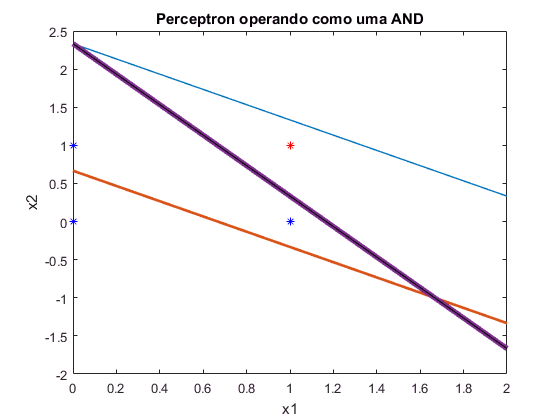

%% Treinamento da Rede Perceptron Simples
% A rede Perceptron é utilizada para modelar o comportamento de uma porta lógica AND.
%
 
clc
clear
close
x = [0 0;
    0 1;
    1 0;
    1 1];
d = [0; 0; 0; 1];
w = zeros(1,2);
bias = -1;
a = 0.3;
epocamax = 50;
e = [1 1 1 1];
E = sum(abs(e));
epoca = 0;
figure(1);
while((epoca < epocamax)&&(E > 0))
    for i = 1:4
        u(i) = x(i,:)*w' + bias;
        
        if(u(i) <= 0)
            y(i) = 0;
        else
            y(i) = 1;
        end
        e(i) = d(i) - y(i);
        w = w + a*e(i)*x(i,:);
        bias = bias + a*e(i);
        
    end
    epoca = epoca + 1;
    w1 = w(1); w2 = w(2);
    E = sum(abs(e));
    x1 = 0:0.01:2;
    x2 = -(bias + x1*w1)/w2;
    plot(x1,x2,'LineWidth',epoca);
    hold on
    
end
w1 = w(1,1);
w2 = w(1,2);
% x1*w1 + x2*w2 +bias = 0
x1 = 0:0.01:2;
x2 = -(bias + x1*w1)/w2;
figure(1)
plot(x1,x2,'k');
title('Perceptron operando como uma AND');
xlabel('x1');
ylabel('x2');
hold on

h1 = x(:,1);
h2 = x(:,2);
for i=1:4
    if (h1(i) == 1)&&(h2(i) == 1)
        plot(h1(i),h2(i),'*r');
        hold on
    else
        hold on
        plot(h1(i),h2(i),'*b');
    end
end

disp(epoca)

     4


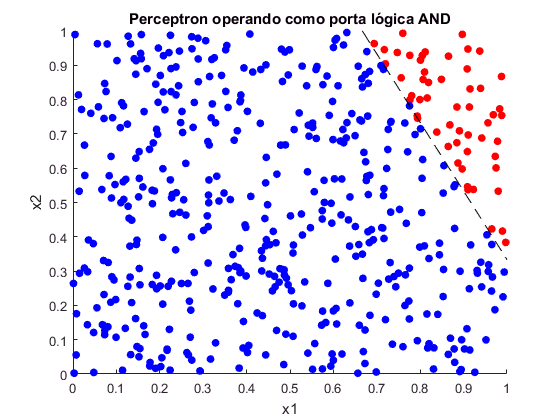

%% Teste da Rede Perceptron Simples
% Neste trecho, após o treinamento da rede Perceptron, será realizado o teste dos 
% pesos encontrados pela rede. Plotou-se os gráficos para as entradas x1 e x2 
% (x2 em função de x1) e seus respectivos pesos.
close
teste = rand(500,2);
r = size(teste); % pega o tamanho da matriz teste
r1 = r(1,1); % número de linhas
r2 = r(1,2); % número de colunas
for i=1:r1
    v(i) = teste(i,:) * w' + bias; % Potencial de ativação
    if (v(i) <= 0)
        saida(i) = 0;
    else
        saida(i) = 1;
    end
end
x1 = teste(:,1);
x2 = teste(:,2);
figure(2);
for h=1:r1
    title('Perceptron operando como porta lógica AND');
    if (saida(h) == 1)
        plot(x1(h),x2(h),'.r','MarkerSize',20); 
        hold on
    else
        hold on
        plot(x1(h),x2(h),'.b','MarkerSize',20);
    end
end
xlabel('x1');
ylabel('x2');
axis([0 1 0 1]);
hold on
W1 = w(:,1);
W2 = w(:,2);
X1=0:0.01:2;
X2 = (-X1*W1 - bias)/W2;
plot(X1,X2,'--k');